# Demo 3: Reflection from multilayer structures

In Demo 1, we learned about reflection and transmission at a planar air-dielectric interface. Our analysis can, in fact, be extended to planar interfaces between more complicated materials (lossy, anisotropic, and so on) as well as *multilayer structures*, where there are *many planar interfaces* between *many materials*. Another term for these systems that you may have heard is *one-dimensional (1D) photonic crystals*.

## Recursion relation for the reflection coefficient

The system we are interested in analyzing is shown in the figure below. It consists of an $N$-layer multilayer structure, where the incident and reflected waves are in the 0th layer and the transmitted wave is in the $\left(N+1\right)$th layer.

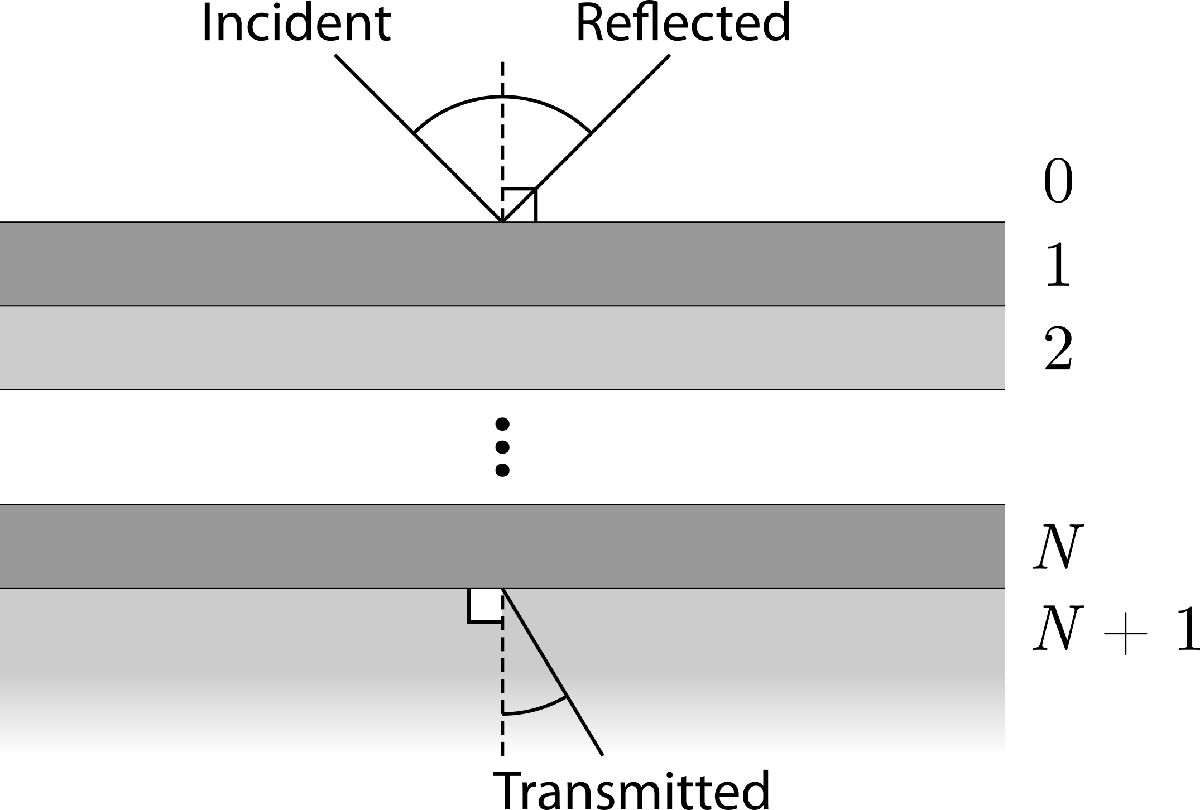

In our case, we assume that each layer is isotropic ($\overline{\overline{\varepsilon}}=\varepsilon\overline{\overline{I}}$ where $\overline{\overline{I}}$ is the identity matrix) and nonmagnetic ($\mu=1$). The layers can be lossy ($\varepsilon\in\mathbb{C}$). Using Poynting flux arguments similar to those used in Demo 1, the reflectance of the multilayer structure should be


$$R={\left|\frac{E_r }{E_i }\right|}^2 \ldotp$$


What this equation means for us is that we need to solve for the amplitude ratio $E_r /E_i ,$ where $E_r$ and $E_i$ live in the 0th layer. To do so, let us zoom in on a single layer, the $j$th layer, shown in the figure below.

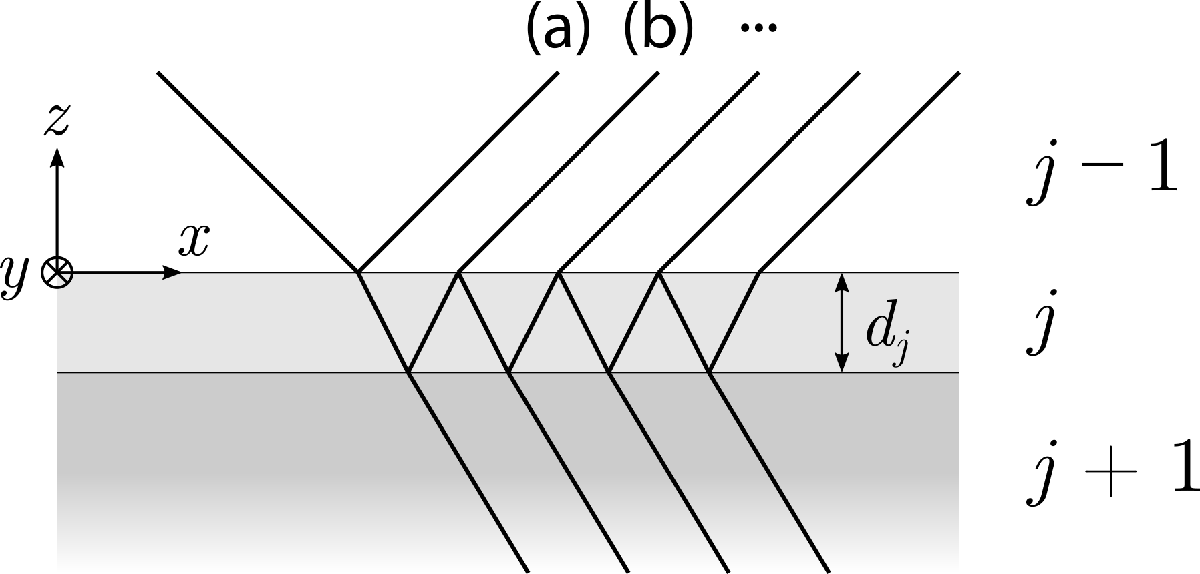

A wave incident on the $j$th layer will experience multiple reflections. If the electric field of the incident wave is $E_i^{\left(j-1\right)} ,$ the *total* reflected wave can be written in the form of an infinite sum accounting for each of the multiple reflections. We can determine each term of the infinite sum by *ray tracing*. Consider, for example, the reflected wave (a) in the figure above. In this case, the incident wave experiences only one reflection: at the interface between layer $\left(j-1\right)$ and layer $j\ldotp$ Therefore,


$$E_r^{\left(a\right)} =r_{j-1,j} E_i^{\left(j-1\right)} ,$$


where $r_{j-1,j}$ is the appropriate reflection coefficient at the interface between layer $\left(j-1\right)$ and layer $j\ldotp$ (By "appropriate," we mean appropriate for the polarization, *p* or *s*, of the incident wave.)

Now consider the reflected wave (b) in the figure above. In this case, the incident wave:

- is transmitted from layer $\left(j-1\right)$ to layer $j,$

- propagates a distance of $d_j$ in layer $j$ (i.e., it acquires a *phase shift* of $e^{{\textrm{ik}}_{\textrm{zj}} d_j } ,$ where $k_{\textrm{zj}} =\sqrt{\varepsilon_j k_0^2 -k_x^2 }$ is the $z$-component of the wavevector in layer $j$),

- is reflected at the interface between layer $j$ and $\left(j+1\right),$

- propagates a distance of $d_j$ in layer $j$ once again,

- is transmitted from layer $j$ to $\left(j-1\right)$, finally.

The electric field of the reflected wave (b) is $E_i$ multiplied by the effect of each step:


$$\begin{array}{l}
E_r^{\left(b\right)} =\underset{\left(1\right)}{t_{j-1,j} } \times \;\underset{\left(2\right)}{e^{{\textrm{ik}}_{\textrm{zj}} d_j } } \times \;\underset{\left(3\right)}{r_{j,j+1} } \times \underset{\left(4\right)}{e^{{\textrm{ik}}_{\textrm{zj}} d_j } } \times \underset{\left(5\right)}{t_{j,j-1} } E_i^{\left(j-1\right)} \\
E_r^{\left(b\right)} =t_{j-1,j} r_{j,j+1} t_{j,j-1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)} \ldotp 
\end{array}$$


This line of thinking, or *ray tracing*, can be applied to each of the multiple reflections. Going back to the idea of an infinite sum, the electric field of the total reflected wave is


$$E_r^{\left(j-1\right)} =E_r^{\left(a\right)} +E_r^{\left(b\right)} +E_r^{\left(c\right)} +E_r^{\left(d\right)} +\ldotp \ldotp \ldotp$$



$$=r_{j-1,j} E_i^{\left(j-1\right)} +t_{j-1,j} r_{j,j+1} t_{j,j-1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)} +t_{j-1,j} r_{j,j+1} r_{j,j-1} r_{j,j+1} t_{j,j-1} e^{4{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)} +t_{j-1,j} r_{j,j+1} r_{j,j-1} r_{j,j+1} r_{j,j-1} r_{j,j+1} t_{j,j-1} e^{6{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)} +\ldotp \ldotp \ldotp$$



$$=r_{j-1,j} E_i^{\left(j-1\right)} +t_{j-1,j} t_{j,j-1} \left(r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \right)E_i^{\left(j-1\right)} +t_{j-1,j} t_{j,j-1} r_{j,j-1} {\left(r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \right)}^2 E_i^{\left(j-1\right)} +t_{j-1,j} t_{j,j-1} r_{j,j-1}^2 {\left(r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \right)}^3 E_i^{\left(j-1\right)} +\ldotp \ldotp \ldotp$$



$$=r_{j-1,j} E_i^{\left(j-1\right)} +t_{j-1,j} t_{j,j-1} \sum_{n=1}^{\infty \;} r_{j,j-1}^{n-1} {\left(r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \right)}^n E_i^{\left(j-1\right)}$$



$$=r_{j-1,j} E_i^{\left(j-1\right)} +t_{j-1,j} t_{j,j-1} \sum_{n=1}^{\infty \;} {\left(r_{j,j-1} r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \right)}^{n-1} \left(r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)} \right)$$


The second term in the above equation should look familiar: it is an infinite geometric sum!


$$\sum_{n=1}^{\infty \;} {\alpha \rho \;}^{n-1} =\frac{\alpha }{1-\rho }\ldotp$$


In this case, $\alpha =r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } E_i^{\left(j-1\right)}$ and $\rho =r_{j,j-1} r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } \ldotp$ Factoring out and dividing by $E_i^{\left(j-1\right)} ,$ the amplitude ratio $E_r^{\left(j-1\right)} /E_i^{\left(j-1\right)}$ is


$$\Gamma_{j-1} =r_{j-1,j} +t_{j-1,j} t_{j,j-1} \frac{r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } }{1-r_{j,j-1} r_{j,j+1} e^{2{\textrm{ik}}_{\textrm{zj}} d_j } }\ldotp$$


This can be turned into a *recursion relation* by recognizing that $r_{j,j+1}$ can be replaced by $\Gamma_j$ since $r_{j,j+1} =E_r^{\left(j\right)} /E_i^{\left(j\right)} ,$ which itself depends on multiple reflections in layer $\left(j+1\right)\ldotp$ Therefore,


$$\Gamma_{j-1} =r_{j-1,j} +t_{j-1,j} t_{j,j-1} \frac{\Gamma_j e^{2{\textrm{ik}}_{\textrm{zj}} d_j } }{1-r_{j,j-1} \Gamma_j e^{2{\textrm{ik}}_{\textrm{zj}} d_j } },$$


where the recursion relation is initialized by $\Gamma_N =r_{N,N+1}$ or, equivalently, $\Gamma_{N+1} =0\ldotp$ Finally, the reflectance of the multilayer structure is


$$R={\left|\Gamma_0 \right|}^2 ,$$


where $\Gamma_0$ is the *total reflection coefficient* of the multilayer structure.

## Part 1

### Simplifying the recursion relation

When we derived the recursion relation, you may have noticed that we did not make any assumptions about the relationships between the reflection and transmission coefficients. However, we know they are related via the boundary conditions for electromagnetic fields:


$$1+r=t,$$


if $r$ and $t$ are defined in terms of the $x$-components of the electric fields.* In addition, you may recall that


$$r_{j-1,j}^p =\frac{\varepsilon_{j-1} k_{\textrm{zj}} -\varepsilon_j k_{\textrm{zj}-1} }{\varepsilon_{j-1} k_{\textrm{zj}} +\varepsilon_j k_{\textrm{zj}-1} }$$


in the case of *p*-polarized light and


$$r_{j-1,j}^s =\frac{k_{\textrm{zj}} -k_{\textrm{zj}-1} }{k_{\textrm{zj}} +k_{\textrm{zj}-1} }$$


in the case of *s*-polarized light. In either case, it is straightforward to show that $r_{j-1,j} =-r_{j,j-1}$ by swapping the indices. **Using this information, show that**


$$\Gamma_{j-1} =\frac{r_{j-1,j} +\Gamma_j e^{2{\textrm{ik}}_{\textrm{zj}} d_j } }{1+r_{j-1,j} \Gamma_j e^{2{\textrm{ik}}_{\textrm{zj}} d_j } }\ldotp$$


*(*For the reflection coefficient and reflectance, it turns out that it does not matter whether they are defined in terms of the *$x$*-components of the electric fields or the amplitudes. For the transmission coefficient and transmittance, this definition will change things up a little bit.)*

## Part 2

Open the file `multilayer.m` and complete the function that calculates the reflectance of *any* multilayer structure. A modified version of `reflCoeff.m` (from Demo 1) that is more suitable for this calculation is provided for you.

### Thin film interference in soap bubbles

You may have noticed, while absent-mindedly washing your hands or doing the dishes, that soap bubbles can appear colorful and have rainbows.

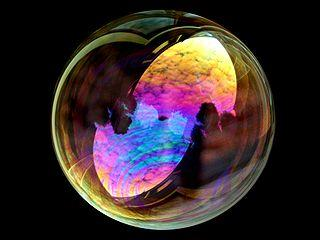

*(Photo courtesy of Brocken Inaglory, from Wikimedia Commons.)*

#### Calculating the reflectance

Assuming the refractive index of soap is 1.33, complete the code below and use `multilayer.m` to calculate the reflectance of a soap bubble as a function of wavelength and film thickness.

Hint: Think of a thin film such as the soap bubble as a multilayer structure. What is $N$? Keep in mind that the soap bubble is suspended in air ($n=1$). Also, $\varepsilon =n^2 \ldotp$

clear;

c = 3e8;

lambda = (300:700)*1e-9; % Wavelength [m].
omega = 2*pi*c./lambda; % Angular frequency [rad/s].
theta = pi/4; % Polar angle of incidence [rad].

d = (200:200:1000)*1e-9; % Film thickness [m].

% Preallocate arrays.
R_p = zeros(length(d), length(omega)); % p-polarized reflectance.
R_s = zeros(length(d), length(omega)); % s-polarized reflectance.

% Loop over d and omega.
% === TYPE YOUR CODE BELOW === %







R = (R_p + R_s)/2; % Total reflectance.

Plot the results of your calculation. What do you notice?

% === TYPE YOUR CODE BELOW === %






#### Interference conditions

Although the reflectance is relatively low (which should make sense because soap bubbles are translucent even when they appear colorful), the maxima of the reflectance spectrum tell us which color should be visible at a given film thickness, roughly speaking.** It turns out that the condition for constructive interference in soap bubbles is


$$2d\sqrt{n^2 -\sin^2 \theta \;}=\left(m-\frac{1}{2}\right)\lambda ,$$


where $m$ is an integer.** In other words, the above equation should tell you where the maxima of the reflectance spectrum are. Complete the code below calculate the locations of the maxima as a function of $d$ and $m\ldotp$

*(**In reality, you should convert the reflectance spectrum to a color using the color matching functions: https://en.wikipedia.org/wiki/CIE_1931_color_space. This will be the subject of another demo.)*

m = 1:10; % Interference order.

% Preallocate array.
maximaLocations = zeros(length(d), length(m));

% Loop over d and omega.
% === TYPE YOUR CODE BELOW === %






table(maximaLocations/1e-9, 'RowNames', string(d/1e-9))

Finally, extract the locations of the maxima using the reflectance spectra you calculated. Compare your results. What are the interference orders $m$ of the maxima you can see in the reflectance spectra you plotted?

Hint: loop over `d` and use the function `islocalmin`.

% === TYPE YOUR CODE BELOW === %











## Part 3

### (a) Anti-reflection coating

Besides adding whismy to your dishwashing routine, thin films can be used to design *anti-reflection coatings*. An anti-reflection coating is made of a material having a refractive index higher than that of air (> 1) but lower than that of the substrate.

#### The quarter-wavelength rule

The condition for destructive interference in anti-reflection coatings is


$$2d\sqrt{n^2 -\sin^2 \theta \;}=\left(m-\frac{1}{2}\right)\lambda$$


Show that, at normal incidence, the *optical thickness* $\textrm{dn}$ should satisfy


$$\textrm{dn}=\frac{\lambda \;}{4}\ldotp$$


#### Glasses

*Magnesium fluoride* is a commonly used anti-reflection coating for glasses. Suppose we would like to minimize reflection and maximize transmission at a wavelength of 500 nm (green light). Design an anti-reflection coating using the quarter-wavelength rule. Calculate and plot the reflectance as a function of wavelength, with and without the anti-reflection coating. By what percentage does the reflectance decrease at 500 nm? Assume the refractive indices of magnesium fluoride and glass are 1.38 and 1.5, respectively.

theta = 0;

n_MgF2 = 1.38;
n_SiO2 = 1.5;

% Calculate the film thickness using the quarter-wavelength rule.
% === TYPE YOUR CODE BELOW === %


% Preallocate arrays.
R_coated = zeros(1, length(omega));
R_uncoated = zeros(1, length(omega));

% Reflectance WITH the anti-reflection coating.
% === TYPE YOUR CODE BELOW === %






% Reflectance WITHOUT the anti-reflection coating.
% === TYPE YOUR CODE BELOW === %






% Plot.
% === TYPE YOUR CODE BELOW === %








### (b) Bragg mirror

A *Bragg mirror* is a multilayer structure in the same family as anti-reflection coatings. It consists of alternating high- and low-refractive index materials, with each layer of the structure following the quarter-wavelength rule. Your task is to investigate how the reflectance spectrum of a Bragg mirror changes with the number of layers in the structure.

We will consider a Bragg mirror consisting of magnesium fluoride ($n=1\ldotp 38$) as the low-refractive index material and zinc sulfide ($n=2\ldotp 32$) as the high-refractive index material. Just like before, the substrate is glass ($n=1\ldotp 5$). Complete the code below to generate the inputs for multilayer.m given the number of layers $N\ldotp$

% You can adjust the slider below to change the number of layers!
N =34;

n_MgF2 = 1.38;
n_ZnS = 2.32;
n_SiO2 = 1.5;

% Preallocate arrays.
d = [];
epsilon = [];

% 0th layer: air.
epsilon = [epsilon, 1];

% === TYPE YOUR CODE BELOW === %












% (N+1)th layer: glass.
epsilon = [epsilon, n_SiO2^2];

Complete the code below to calculate the reflectance of as a function of wavelength.

% Preallocate arrays.
R_p = zeros(1, length(omega));
R_s = zeros(1, length(omega));

% Loop over omega.
% === TYPE YOUR CODE BELOW === %





R = (R_p + R_s)/2; % Total reflectance.

Each time you adjust the slider, the below code will replot the reflectance spectrum, keeping the previous plots. Play around with the slider. What do you notice as you increase the number of layers?

plot(lambda/1e-9, R, 'DisplayName', num2str(N));
hold on;
xlabel('Wavelength [nm]');
ylabel('Reflectance [1]');
ylim([0,1]);
l = legend('Location', 'eastoutside');
l.Title.String = 'Number of layers [1]';